## Nonlinear system: First-order ARX model with one delay + static nonlinearity

Model: $(q + a_1) y(k) = (b_0 q + b_1) q^{-1}u(k) + e(k+1)$

% Generate some data
z = tf('z', 1);
% Transfer function
G0 = (z+0.8)/(z*(z-0.8))

G0 =
 
    z + 0.8
  -----------
  z^2 - 0.8 z
 
Sample time: 1 seconds
Discrete-time transfer function.



% Error model
Ge = z/((z-0.8))

Ge =
 
     z
  -------
  z - 0.8
 
Sample time: 1 seconds
Discrete-time transfer function.



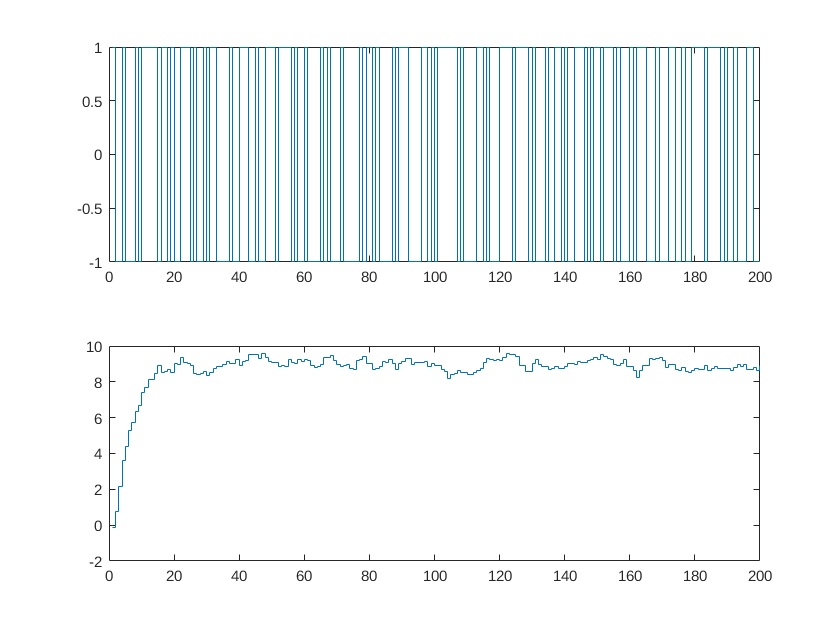

% Input data
u1uv = idinput(400);
u1 = u1uv(1:200);
u1v = u1uv(201:end);

% Perturbation-free output
y10 = lsim(G0, u1.^2);
y10v = lsim(G0, u1v.^2);

% Output with perturbation
e = 0.2*randn(size(u1));
y1 = y10 + lsim(Ge, e);
ev = 0.2*randn(size(u1v));
y1v = y10v + lsim(Ge, ev);

%Plot the data
figure()
subplot(211)
stairs(u1);
subplot(212)
stairs(y1)

### Estimate the parameters

The one-step ahead predictor:


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k) + b_1u(k-1) = \pmatrix{ -y(k) & u(k) & u(k-1)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


The residual vector:


$$\epsilon = y - \Phi\theta$$


Phi = cat(2, -y1(2:end-1), u1(2:end-1), u1(1:end-2));
y = y1(3:end);
theta1 = Phi\y

theta1 =    -1.0021
   -0.0017
   -0.0110


display(sprintf('a_1 = %f', theta1(1)))

a_1 = -1.002101


display(sprintf('b_0 = %f', theta1(2)))

b_0 = -0.001719


fprintf('b_1 = %f\n', theta1(3))

b_1 = -0.010992


G11 = (theta1(2)*z + theta1(3))/(z*(z+theta1(1)))

G11 =
 
  -0.001719 z - 0.01099
  ---------------------
      z^2 - 1.002 z
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Fitting higher-order models

iddta1 = iddata(y1,u1, 1);
valdta1 = iddata(y1v, u1v, 1);
arx331 = arx(iddta1, [3, 3, 1])

arx331 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t) 
  A(z) = 1 - 1.207 z^-1 - 0.08476 z^-2 + 0.2915 z^-3
                                                    
  B(z) = 0.01173 z^-1 - 0.0146 z^-2 - 0.004995 z^-3 
                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 81.61% (prediction focus)
FPE: 0.05358, MSE: 0.04897                       


arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                 
  A(z) = 1 - 1.056 z^-1 - 0.1652 z^-2 + 0.0594 z^-3 + 0.1611 z^-4   
                                                                    
  B(z) = 0.01761 z^-1 - 0.006301 z^-2 - 0.01011 z^-3 + 0.005744 z^-4
                                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 82.91% (prediction focus)
FPE: 0.04768, MSE: 0.04228                       


arx551 = arx(iddta1, [5, 5, 1])

arx551 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                 
  A(z) = 1 - 1.023 z^-1 - 0.1659 z^-2 + 0.03574 z^-3 + 0.1224 z^-4 + 0.0305 z^-5    
                                                                                    
  B(z) = 0.01511 z^-1 - 0.003586 z^-2 - 0.008429 z^-3 + 0.003225 z^-4 - 0.01843 z^-5
                                                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=5   nk=1
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 83.06% (prediction focus)
FPE: 0.04832, MSE: 0.04157                       


arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                 
  A(z) = 1 - 1.007 z^-1 - 0.1207 z^-2 + 0.02649 z^-3 + 0.08046 z^-4 - 0.04462 z^-5 + 0.06497 z^-6   
                                                                                                    
  B(z) = 0.01416 z^-1 - 0.005185 z^-2 - 0.004916 z^-3 + 0.005854 z^-4 - 0.0214 z^-5 + 0.0007959 z^-6
                                                                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 83.3% (prediction focus) 
FPE: 0.04837, MSE: 0.04038                       


arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                 
  A(z) = 1 - 0.9418 z^-1 - 0.1376 z^-2 + 0.04191 z^-3 + 0.1434 z^-4 - 0.05443 z^-5 - 0.1914 z^-6 - 0.03053 z^-7 + 0.1705 z^-8       
                                                                                                                                    
  B(z) = 0.01306 z^-1 - 0.009957 z^-2 - 0.007826 z^-3 + 0.008025 z^-4 - 0.01252 z^-5 + 0.002542 z^-6 - 0.009397 z^-7 - 0.009127 z^-8
                                                                                                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 

arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                          
                                                                                                                                                             
  A(z) = 1 - 0.8874 z^-1 - 0.1204 z^-2 + 0.03809 z^-3 + 0.1696 z^-4 - 0.09496 z^-5 - 0.1355 z^-6 - 0.04402 z^-7 + 0.07093 z^-8 + 0.02913 z^-9 - 0.1718 z^-10 
                                                                                                                            + 0.1165 z^-11 + 0.02995 z^-12   
                                                                                                                                                             
                                                                                                                                                             
  B(z) = 0.008438 z^-1 - 0.008552 z^-2 - 

#### Compare the models

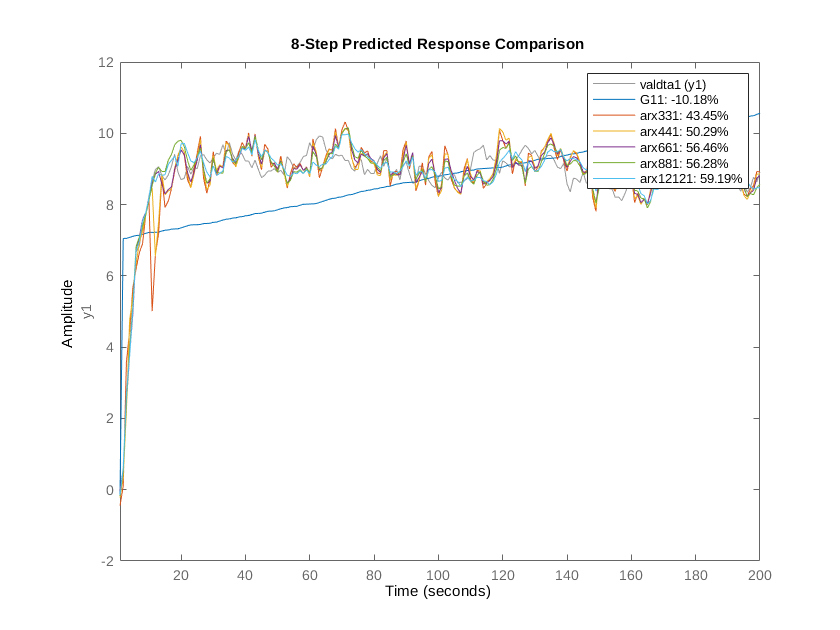

figure
compare(valdta1, G11, arx331, arx441, arx661, arx881, arx12121, 8)

pole(arx331)

ans =     1.0009
    0.6526
   -0.4463


pole(arx12121)

ans =    0.9999 + 0.0000i
   0.8014 + 0.0000i
   0.6674 + 0.5392i
   0.6674 - 0.5392i
   0.3195 + 0.7275i
   0.3195 - 0.7275i
  -0.2741 + 0.8047i
  -0.2741 - 0.8047i
  -0.6693 + 0.5016i
  -0.6693 - 0.5016i


pzmap

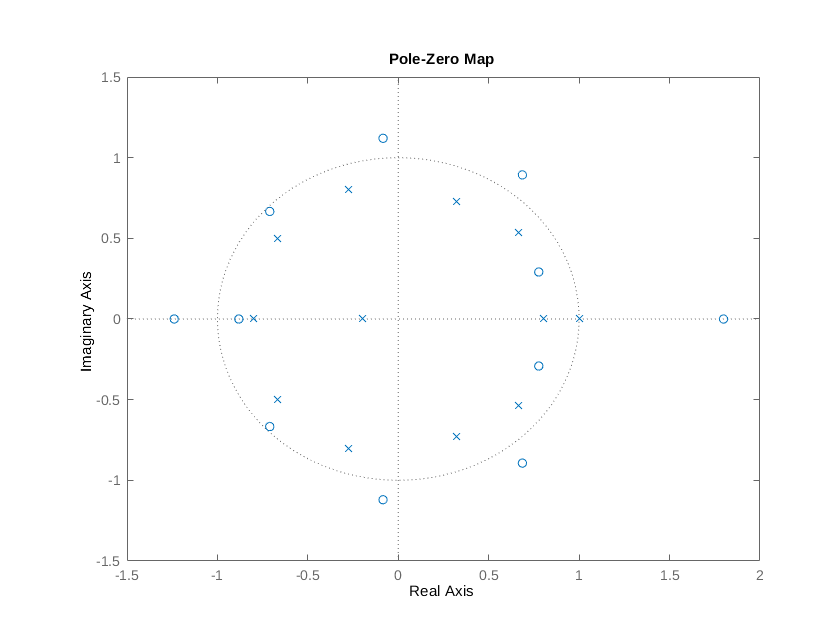

pzmap(arx12121)

## First-order ARX model with one delay + integrator

Model: $(q + a_1)(q-1) y(k) = (b_0 q + b_1) u(k) + e(k+1)$

% Generate some data
z = tf('z', 1);
% Transfer function
G0 = (z+0.8)/((z-1)*(z-0.8))

G0 =
 
       z + 0.8
  -----------------
  z^2 - 1.8 z + 0.8
 
Sample time: 1 seconds
Discrete-time transfer function.



% Error model
Ge = z/((z-1)*(z-0.8))

Ge =
 
          z
  -----------------
  z^2 - 1.8 z + 0.8
 
Sample time: 1 seconds
Discrete-time transfer function.



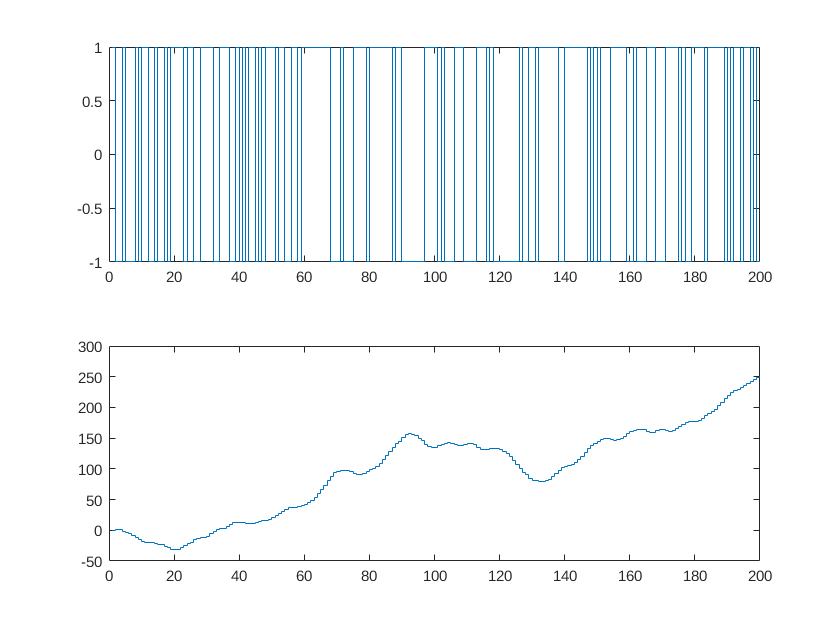

% Input data
u1uv = idinput(400);
u1 = u1uv(1:200);
u1v = u1uv(201:end);

% Perturbation-free output
y10 = lsim(G0, u1);
y10v = lsim(G0, u1v);

% Output with perturbation
e = 0.2*randn(size(u1));
y1 = y10 + lsim(Ge, e);
ev = 0.2*randn(size(u1v));
y1v = y10v + lsim(Ge, ev);

%Plot the data
figure()
subplot(211)
stairs(u1);
subplot(212)
stairs(y1)

### Estimate the parameters

The one-step ahead predictor:


$$ \hat{y}(k+1) = -a_1y(k) + b_0u(k) + b_1u(k-1) = \pmatrix{ -y(k) & u(k) & u(k-1)} \pmatrix{ a_1 \cr b_0 \cr b_1}
 = \varphi_{k+1}^T\theta$$


The residual vector:


$$\epsilon = y - \Phi\theta$$


Phi = cat(2, -y1(2:end-1), u1(2:end-1), u1(1:end-2));
y = y1(3:end);
theta1 = Phi\y

theta1 =    -1.0078
    1.0280
    1.7548


display(sprintf('a_1 = %f', theta1(1)))

a_1 = -1.007805


display(sprintf('b_0 = %f', theta1(2)))

b_0 = 1.028031


fprintf('b_1 = %f\n', theta1(3))

b_1 = 1.754808


G11 = (theta1(2)*z + theta1(3))/(z*(z+theta1(1)))

G11 =
 
  1.028 z + 1.755
  ---------------
   z^2 - 1.008 z
 
Sample time: 1 seconds
Discrete-time transfer function.



#### Fitting higher-order models

iddta1 = iddata(y1,u1, 1);
valdta1 = iddata(y1v, u1v, 1);
arx221 = arx(iddta1, [2, 2, 1])

arx221 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 1.788 z^-1 + 0.7882 z^-2              
                                                   
  B(z) = 0.9901 z^-1 + 0.8078 z^-2                 
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=2   nk=1
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.77% (prediction focus)
FPE: 0.03005, MSE: 0.0283                        


arx331 = arx(iddta1, [3, 3, 1])

arx331 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t) 
  A(z) = 1 - 1.721 z^-1 + 0.6702 z^-2 + 0.05099 z^-3
                                                    
  B(z) = 0.988 z^-1 + 0.8758 z^-2 + 0.06282 z^-3    
                                                    
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nk=1
   Number of free coefficients: 6
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.78% (prediction focus)
FPE: 0.02972, MSE: 0.02716                       


arx441 = arx(iddta1, [4, 4, 1])

arx441 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)               
  A(z) = 1 - 1.708 z^-1 + 0.6237 z^-2 + 0.1059 z^-3 - 0.02179 z^-4
                                                                  
  B(z) = 0.9866 z^-1 + 0.888 z^-2 + 0.05058 z^-3 - 0.0003925 z^-4 
                                                                  
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nk=1
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.78% (prediction focus)
FPE: 0.03019, MSE: 0.02677                       


arx551 = arx(iddta1, [5, 5, 1])

arx551 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                             
  A(z) = 1 - 1.699 z^-1 + 0.6144 z^-2 - 0.04637 z^-3 + 0.2474 z^-4 - 0.1165 z^-5
                                                                                
  B(z) = 0.9881 z^-1 + 0.8934 z^-2 + 0.06203 z^-3 - 0.1392 z^-4 - 0.1208 z^-5   
                                                                                
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=5   nb=5   nk=1
   Number of free coefficients: 10
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.78% (prediction focus)
FPE: 0.03016, MSE: 0.02595                       


arx661 = arx(iddta1, [6, 6, 1])

arx661 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                             
  A(z) = 1 - 1.688 z^-1 + 0.6033 z^-2 - 0.04213 z^-3 + 0.1967 z^-4 - 0.03873 z^-5 - 0.03119 z^-6
                                                                                                
  B(z) = 0.9872 z^-1 + 0.9056 z^-2 + 0.07786 z^-3 - 0.1225 z^-4 - 0.149 z^-5 - 0.02611 z^-6     
                                                                                                
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=6   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.78% (prediction focus)
FPE: 0.03089, MSE: 0.02579                       


arx881 = arx(iddta1, [8, 8, 1])

arx881 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                       
  A(z) = 1 - 1.692 z^-1 + 0.6098 z^-2 - 0.03031 z^-3 + 0.1811 z^-4 - 0.0345 z^-5 - 0.155 z^-6 + 0.2086 z^-7 - 0.08749 z^-8
                                                                                                                          
  B(z) = 0.9878 z^-1 + 0.9021 z^-2 + 0.07423 z^-3 - 0.111 z^-4 - 0.1306 z^-5 - 0.007874 z^-6 - 0.1039 z^-7 - 0.1009 z^-8  
                                                                                                                          
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8   nb=8   nk=1
   Number of free coefficients: 16
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARX on time domain data "iddta1".
Fit to estimation data: 99.79% (prediction focus)
FPE: 0.03209, MSE: 0.025

arx12121 = arx(iddta1, [12, 12, 1])

arx12121 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                       
                                                                                                                                                          
  A(z) = 1 - 1.721 z^-1 + 0.6454 z^-2 - 0.009066 z^-3 + 0.1363 z^-4 - 0.03221 z^-5 - 0.1239 z^-6 + 0.1552 z^-7 + 0.1215 z^-8 - 0.3791 z^-9 + 0.3015 z^-10 
                                                                                                                            - 0.1182 z^-11 + 0.02351 z^-12
                                                                                                                                                          
                                                                                                                                                          
  B(z) = 0.995 z^-1 + 0.8718 z^-2 + 0.03371 z^-3 - 0.1068 z

#### Compare the models

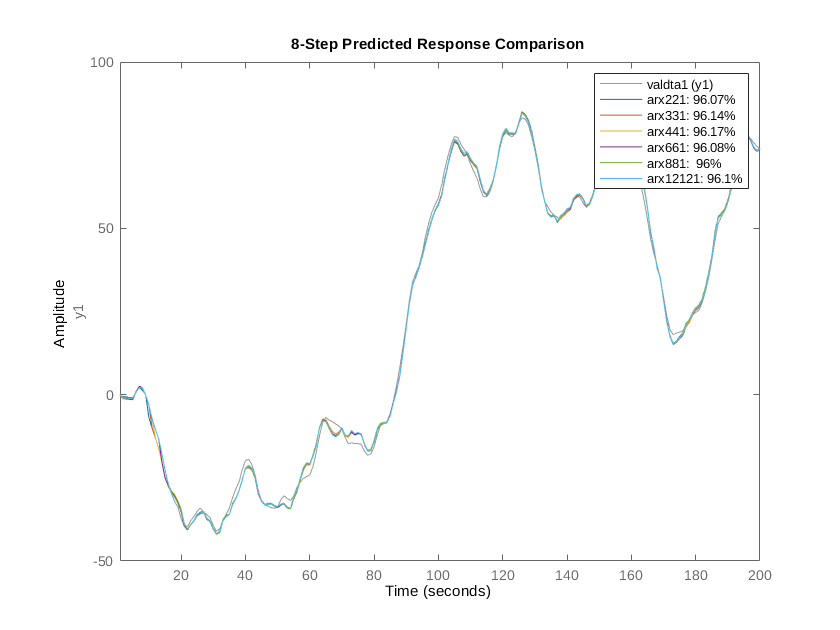

figure
compare(valdta1, arx221, arx331, arx441, arx661, arx881, arx12121, 8)

pole(arx331)

ans =     1.0010
    0.7853
   -0.0649


pole(arx12121)

ans =   -0.7972 + 0.2909i
  -0.7972 - 0.2909i
  -0.4011 + 0.7731i
  -0.4011 - 0.7731i
   0.2472 + 0.6936i
   0.2472 - 0.6936i
   1.0010 + 0.0000i
   0.8394 + 0.0000i
   0.6461 + 0.2129i
   0.6461 - 0.2129i


pzmap

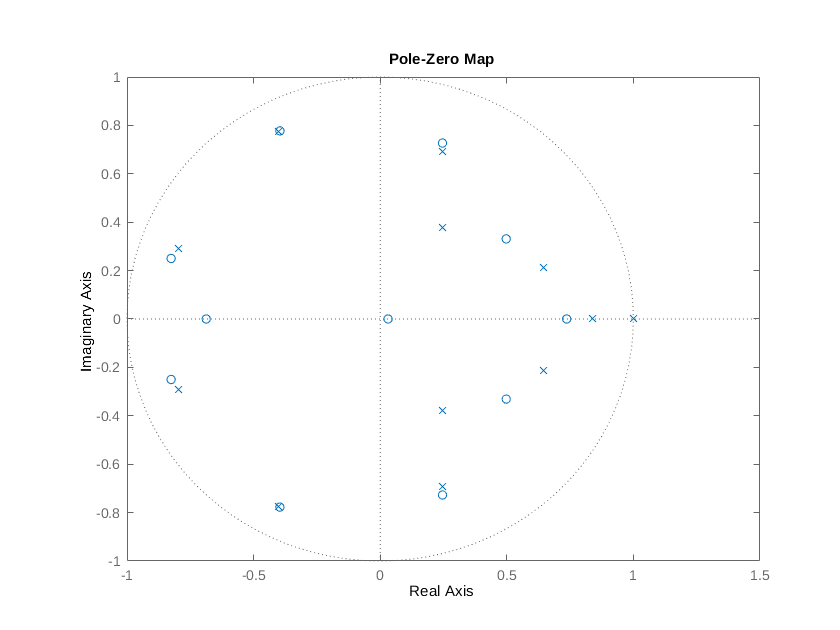

pzmap(arx12121)